# **PRÀCTICA G9: Processament d'imatges a color **

**Número de Grup:**

**Nom:**

Pràctica dissenyada per aplicar els conceptes de Sharpening i Segmentation explicat a classe.

## **Ex1: Correccions de to i color.**

Aplicar les seguents correcions de to i colors a tota la imatge original:

- Sobreexposició (correció de to)

- Subexposició (correcció de to)

- Augmentar saturació (correcció de color)

- Reduir saturació (correcció de color)

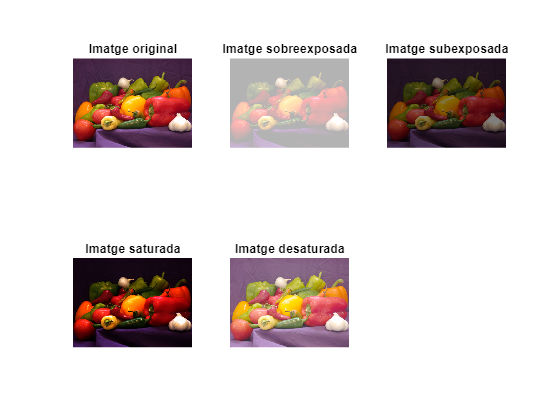

imagen = imread('peppers.png');

%el primer rang especifica el rang d'intensitat d'entrada i el segon el de la sortida 
imagen_sobreexpuesta = imadjust(imagen,[0.3 1], [0.7 1]); 
imagen_subexpuesta = imadjust(imagen,  [0 1], [0 0.5]); %s'oscureix la imatge augmentant el rang de sortida

%indiquem amb [] que TOTS els valors s'han de cambiar de intensitat 
% en aquest cas la indica el factor 2, augmenta saturació
imagen_saturada = imadjust(imagen, [0 1], [], 2);
imagen_desaturada = imadjust(imagen, [0 1], [], 0.5); % el factor 0.5 indica que reduim a la meitat la saturació

% Mostrar les imatges
subplot(2, 3, 1);
imshow(imagen);
title('Imatge original');

subplot(2, 3, 2);
imshow(imagen_sobreexpuesta);
title('Imatge sobreexposada');

subplot(2, 3, 3);
imshow(imagen_subexpuesta);
title('Imatge subexposada');

subplot(2, 3, 4);
imshow(imagen_saturada);
title('Imatge saturada');

subplot(2, 3, 5);
imshow(imagen_desaturada);
title('Imatge desaturada');

## **Ex2: Sharpening Filter utilitzant LaPlacian.**

Resalta els colors de la imatge "flores.jpg", és a dir, fes-la més nitida, per tal de que s'observin els detalls:

NOTA: Podeu anar observant com va canviant la imatge amb diferents kernels.

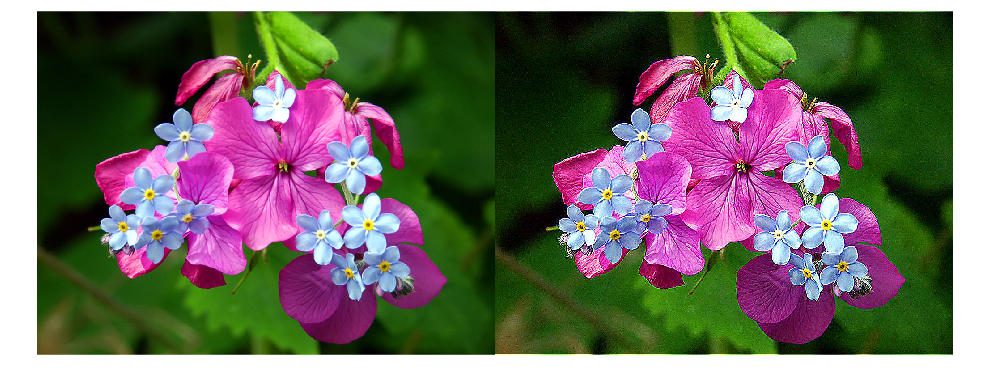

img = imread('flores.jpg');
img = im2double(img);

% Definir el kernel del operador Laplaciano
laplacian_kernel = [0 -1 0; -1 4 -1; 0 -1 0];

% Aplicar el filtro Laplaciano a cada canal de color de la imagen:
% convolucion
R = conv2(img(:,:,1), laplacian_kernel, 'same');
G = conv2(img(:,:,2), laplacian_kernel, 'same');
B = conv2(img(:,:,3), laplacian_kernel, 'same');

% Combinar los canales de color en una sola imagen
imagen_laplaciana = cat(3, R, G, B);

% Aplicar el filtro a la imagen e
factor_intensidad = 2.5; % Se puede ajustar dependiento de como quiero que se vea el sharpening
imagen_laplaciana = img + factor_intensidad * imagen_laplaciana;

% Ajustar los valores de píxeles para estar dentro del rango [0, 1]
imagen_laplaciana = max(0, min(1, imagen_laplaciana));

% Mostrar la imagen original y la imagen mejorada
figure;
imshowpair(img, imagen_laplaciana, 'montage');

## Ex3: Edge filtering

Aplica l'algorisme de Edge Filtering, per tal de resaltar els colors on hi ha un canvi brusc a la imatge "flores.jpg". 

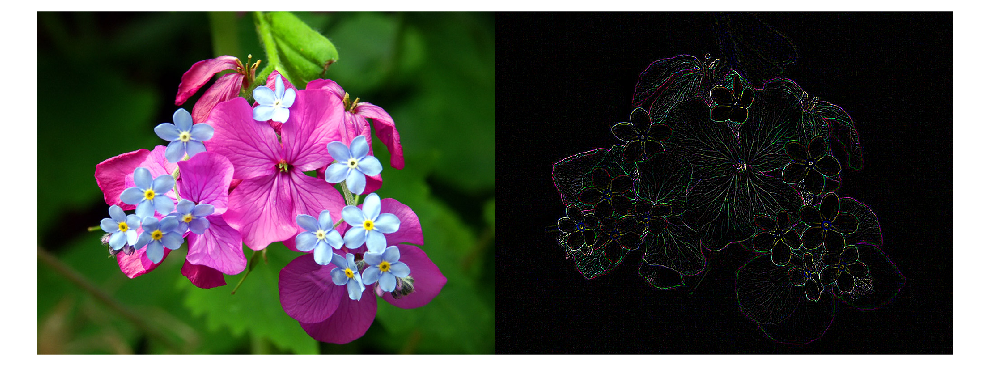

redChannel = img(:,:,1);
greenChannel = img(:,:,2);
blueChannel = img(:,:,3);

% Laplacian filter : includes diagonal terms
laplacianFilter = [1 1 1; 1 -8 1; 1 1 1];

redEdges = conv2(redChannel, laplacianFilter, 'same');
greenEdges = conv2(greenChannel, laplacianFilter, 'same');
blueEdges = conv2(blueChannel, laplacianFilter, 'same');

edgeImage = cat(3, redEdges, greenEdges, blueEdges);

figure;
imshowpair(img, edgeImage, 'montage');

## Ex4: Image Segmentation

Utilitza el "Graph Cut" de l'eina "Image Segmenter" de MatLab  per a separar el fons de l'element principal. Un cop exportada la màscara, executa el següent codi per a crear la visualització la retallada.

Al final de l'execució hauríem de veure una quadrícula semblant a la següent, on clarament es separi l'objecte del fons correctament: (codi ja proporcionat)